# Model Accuracy

This script checks the accuracy of the four prediction model on a given real dataset.

## 🚀 Initialization

clc; clear all;

% Directory
par_dir = '../';

% Load data
filename = 'Tucson_Shif_TypSum_RB_2004_TypOcc_TypBehav_NoTES_03252023_112617';
data = load([par_dir '/real_data/' filename '.mat']);

% Load model for estimation
model_name = 'wshp_comp_spd_model';
load([par_dir '/testbed/WSHP/' model_name '.mat']);
model_name = 'wshp_compspd2power_model';
load([par_dir '/testbed/WSHP/' model_name '.mat']);
model_name = 'wshp_compspd2sen_model';
load([par_dir '/testbed/WSHP/' model_name '.mat']);
model_name = 'wshp_compspd2lat_model';
load([par_dir '/testbed/WSHP/' model_name '.mat']);
model_name = 'wshp_fan_spd_model';
load([par_dir '/testbed/WSHP/' model_name '.mat']);
model_name = 'wshp_fanspd2cfm_model';
load([par_dir '/testbed/WSHP/' model_name '.mat']);

## 🧹 Preprocess

% Check and truncate excess data
if length(data.Measurements) > 1441
    data.Measurements = data.Measurements(1:1441,:);
    data.SupvCtrlSig = data.SupvCtrlSig(1:1441,:);
    data.SimData = data.SimData(1:1441,:);
    if iscell(data.SimData)
        for i = 1:length(data.SimData)
            temp(i,1) = data.SimData{i,1};
        end
        data.SimData = temp;
    end
end

% Process hardware data
hdata_name = fieldnames(data.HardwareData);
hdata = eval(['data.HardwareData.' hdata_name{1}]);
[hdata_sim,~] = hwdata_sent(hdata,data.Measurements);

% Extract data
time_step = [data.Measurements.Timestep]';
sim_zone_temp = [data.SimData.T_z]';
sim_zone_hr = [data.SimData.w_z]';
tstat_spt = [data.SimData.Tz_cspt]';
inlet_water_temp = hdata_sim.("Inlet Water Temp [°C]");
% return_air_temp = [data.Measurements.T_z]';
return_air_temp = hdata_sim.("WSHP Return Air Temp [°C]");
return_air_hr = hdata_sim.("WSHP Avg Return HR [kg/kg]");
wshp_power = [data.Measurements.Power_HVAC]'/1000;  % W to kW
sen_load = hdata_sim.("Meas Sensible Load [kW]");
lat_load = - hdata_sim.("Meas Latent Load [kW]");   % sign seems wrong
air_cfm = hdata_sim.("WSHP Air Flowrate [cfm]");
sys_stat_full = [data.SupvCtrlSig.sys_status]';
sys_stat = sys_stat_full(:,2);
sup_temp = [data.Measurements.T_sup]';
fan_spd = hdata_sim{:, contains(hdata_sim.Properties.VariableNames, 'Fan Speed')};
vdc = compressor_vdc(fan_spd, wshp_power, 0.15);
comp_spd = comp_spd_ratio(vdc);

% Debug with hardware data 
time_step_hdata = hdata.('Simulation Time Step');
sim_zone_temp_hdata = hdata{:, contains(hdata_sim.Properties.VariableNames, 'Sim Zone Temp')};
active_setpoint_hdata = hdata{:, contains(hdata_sim.Properties.VariableNames, 'Sim Cool SP')} + 1.5/1.8;
wshp_power_hdata = hdata{:, contains(hdata_sim.Properties.VariableNames, 'WSHP Power')}/1000;   % W to kW
error_hdata = max(sim_zone_temp_hdata - active_setpoint_hdata, -0.8333);
inlet_water_temp_hdata = hdata{:, contains(hdata_sim.Properties.VariableNames, 'Inlet Water Temp')};
return_air_temp_hdata = hdata{:, contains(hdata.Properties.VariableNames, 'WSHP Return Air Temp')};
return_air_hr_hdata = hdata{:, contains(hdata.Properties.VariableNames, 'WSHP Avg Return HR')};
sen_load_hdata = hdata{:, contains(hdata.Properties.VariableNames, 'Meas Sensible Load')};
lat_load_hdata = - hdata{:, contains(hdata.Properties.VariableNames, 'Meas Latent Load')};  
air_cfm_hdata = hdata{:, contains(hdata.Properties.VariableNames, 'WSHP Air Flowrate')};

    
% Calculate active setpoint
active_setpoint = tstat_spt + 1.5/1.8;

% Calculate the error
error = max(sim_zone_temp - active_setpoint, -0.8333);

% Calculate accumulated error
criteria_series = wshp_power;
reset_threshold = 0.15;
acc_error = accumulated_errors_1min(sim_zone_temp, active_setpoint, criteria_series, reset_threshold);
criteria_series = wshp_power_hdata;
reset_threshold = 0.15;
acc_error_hdata = accumulated_errors(sim_zone_temp_hdata, active_setpoint_hdata, criteria_series, reset_threshold);

## 🔎 Check accuracy on real data (unseen)

% Actual
y1_act = wshp_power_hdata;
y2_act = sen_load_hdata;
y3_act = lat_load_hdata;
y4_act = air_cfm_hdata;
xy1_act = comp_spd_hdata;
xy2_act = fan_spd_hdata;

% Predict
X = [error,  acc_error];
xy1_pred = predict(comp_spd_model,X);
xy2_pred = predict(fan_spd_model,X);
% Smooth speed predicts (optional)
xy1_pred = movmean(xy1_pred, [5,0]);
xy2_pred = movmean(xy2_pred, [5,0]);
X = [inlet_water_temp, return_air_temp, return_air_hr, xy1_pred];
y1_pred = predict(compspd2power_model,X);
y2_pred = predict(compspd2sen_model,X);
y3_pred = predict(compspd2lat_model,X);
X = [xy2_pred];
y4_pred = predict(fanspd2cfm_model,X);

% Create a new figure
figure;

% Subplot 1: wshp_power actual vs predicted
subplot(3,2,1); % This specifies a 2x2 grid, first position
plot(y1_act, 'b-', 'LineWidth', 1.5); hold on; % Actual values in blue
plot(y1_pred, 'r--', 'LineWidth', 1.5); hold off; % Predicted values in red dashed
title('WSHP Power Comparison');
legend('Actual', 'Predicted');
xlabel('Sample Index');
ylabel('Power (Units)');

% Subplot 2: sen_load actual vs predicted
subplot(3,2,2); % Second position
plot(y2_act, 'b-', 'LineWidth', 1.5); hold on;
plot(y2_pred, 'r--', 'LineWidth', 1.5); hold off;
title('Sensible Load Comparison');
legend('Actual', 'Predicted');
xlabel('Sample Index');
ylabel('Load (Units)');

% Subplot 3: lat_load actual vs predicted
subplot(3,2,3); % Third position
plot(y3_act, 'b-', 'LineWidth', 1.5); hold on;
plot(y3_pred, 'r--', 'LineWidth', 1.5); hold off;
title('Latent Load Comparison');
legend('Actual', 'Predicted');
xlabel('Sample Index');
ylabel('Load (Units)');

% Subplot 4: air_cfm actual vs predicted
subplot(3,2,4); % Fourth position
plot(y4_act, 'b-', 'LineWidth', 1.5); hold on;
plot(y4_pred, 'r--', 'LineWidth', 1.5); hold off;
title('Airflow Comparison');
legend('Actual', 'Predicted');
xlabel('Sample Index');
ylabel('Airflow (CFM)');

% Subplot 5: comp_spd actual vs predicted
subplot(3,2,5); % Fourth position
plot(xy1_act, 'b-', 'LineWidth', 1.5); hold on;
plot(xy1_pred, 'r--', 'LineWidth', 1.5); hold off;
title('Compressor Speed Comparison');
legend('Actual', 'Predicted');

xlabel('Sample Index');
ylabel('Speed Ratio');

% Subplot 6: fan_spd actual vs predicted
subplot(3,2,6); % Fourth position
plot(xy2_act, 'b-', 'LineWidth', 1.5); hold on;
plot(xy2_pred, 'r--', 'LineWidth', 1.5); hold off;
title('Fan Speed Comparison');
legend('Actual', 'Predicted');

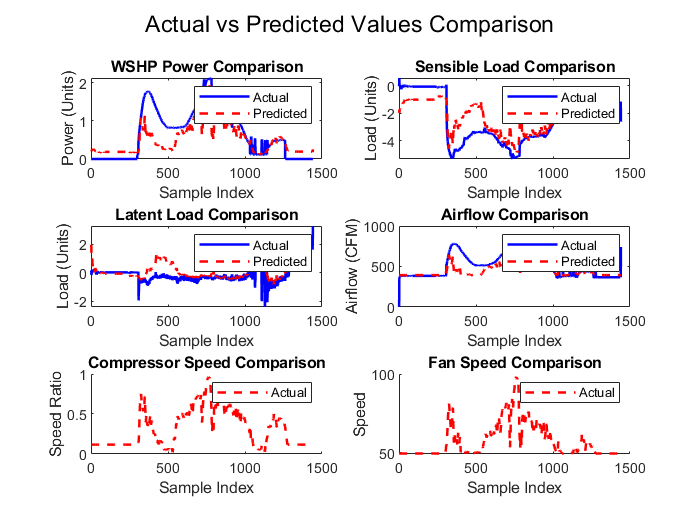

xlabel('Sample Index');
ylabel('Speed');

% Adjust subplot layouts to avoid overlap
sgtitle('Actual vs Predicted Values Comparison'); % Super title for the entire figure